clear

test_data = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\comb_test_results.csv');
true_data = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\comb_true_results.csv');

test_ds_l2 = {};
for i = 1:length(test_data(1,:))
    x = test_data(:,i)';
    x = x(~isnan(x));
    test_ds_l2{i} = x;
end

true_ds_l2 = {};
for i = 1:length(true_data(1,:))
    x = true_data(:,i)';
    x = x(~isnan(x));
    true_ds_l2{i} = x;
end

[~,test_ds_l1,~] = xlsread('C:\Users\adsk1\Documents\FYP\Python\data\plots\comb_test_results.csv');
[~,true_ds_l1,~] = xlsread('C:\Users\adsk1\Documents\FYP\Python\data\plots\comb_true_results.csv');

conf = zeros(5,5);
classes = {'c2o','over','ver','hor','tri'};
test_names = test_ds_l1;
true_names = true_ds_l1;
indices = zeros(1,length(true_names));
for i = 1:length(test_ds_l1)
    test_ind = strcmp(classes,test_ds_l1{i});
    true_ind = strcmp(classes,true_ds_l1{i});
    conf(true_ind,test_ind) = conf(true_ind,test_ind) + 1;
    
    y = strcmp(test_ds_l1{i},true_ds_l1{i});
    if ~y
        indices(i) = 1;
    end
end


for i = 1:length(indices)
    if indices(i)
        true_ds_l2{i} = [];
        test_ds_l2{i} = [];
        true_names{i} = [];
    end
end

true_ds_l2 = true_ds_l2(~cellfun('isempty',true_ds_l2));
test_ds_l2 = test_ds_l2(~cellfun('isempty',test_ds_l2));
names = true_names(~cellfun('isempty',true_names));


data_true = cell(1,5);
data_test = cell(1,5);
for i = 1:length(names)
    name = names{i};
    ind = strcmp(classes,name);
    data_true{ind}(end+1,:) = true_ds_l2{i};
    data_test{ind}(end+1,:) = test_ds_l2{i};
end

avg = cell(1,5);
for i = 1:5
    avg_mat = ((abs(data_true{i} - data_test{i}))./data_true{i})*100;
    avg{i} = mean(avg_mat,1);
end

avg{1,5}(5) = 2;

% c2o
fig = figure()

fig =   Figure (57) with properties:

      Number: 57
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


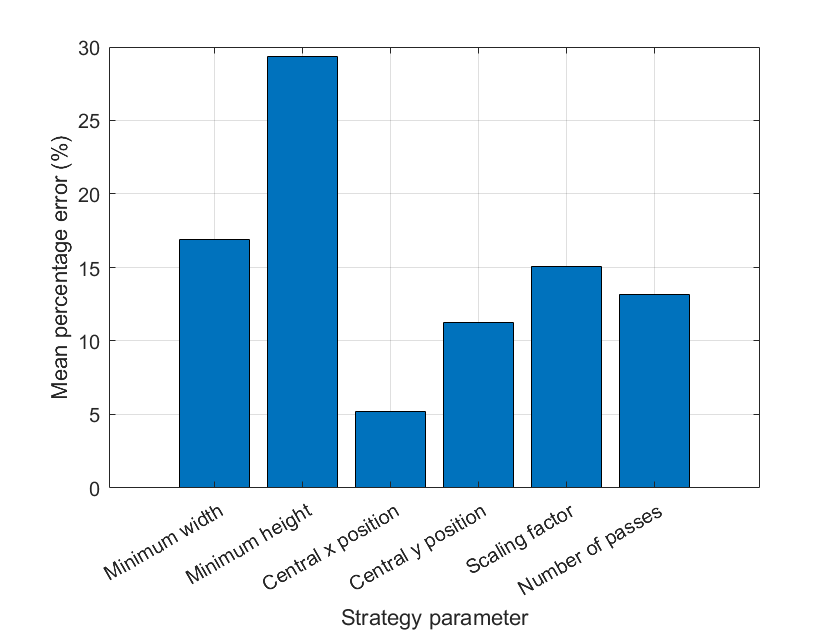

bar(avg{1})
xlabel('Strategy parameter')
ylabel('Mean percentage error (%)')
xticklabels({'Minimum width','Minimum height','Central x position','Central y position','Scaling factor','Number of passes'})
grid on
saveas(fig, '..\Python\data\plots\comb_l2_c2o.jpg')

% over
fig = figure()

fig =   Figure (58) with properties:

      Number: 58
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


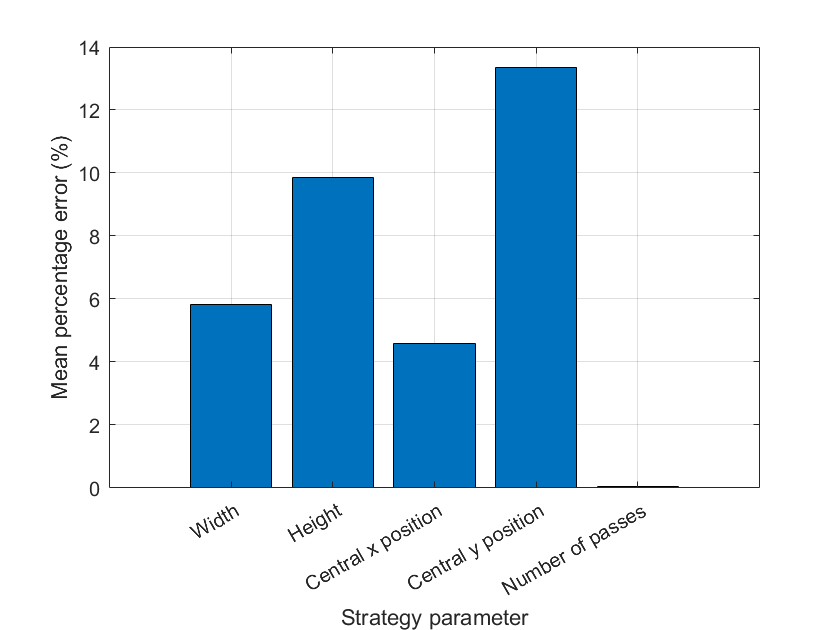

bar(avg{2})
xlabel('Strategy parameter')
ylabel('Mean percentage error (%)')
xticklabels({'Width','Height','Central x position','Central y position','Number of passes'})
grid on

saveas(fig, '..\Python\data\plots\comb_l2_over.jpg')

% ver
fig = figure()

fig =   Figure (59) with properties:

      Number: 59
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


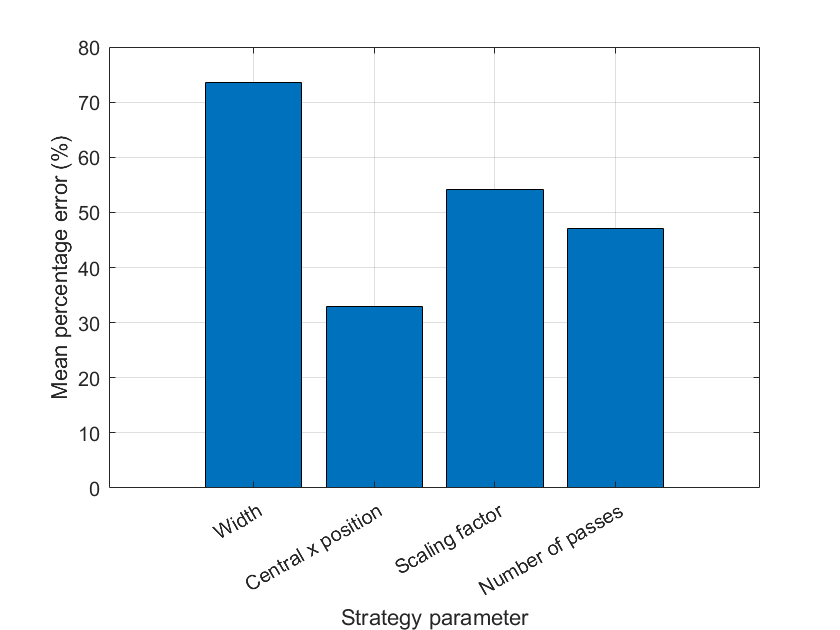

bar(avg{3})
xlabel('Strategy parameter')
ylabel('Mean percentage error (%)')
xticklabels({'Width','Central x position','Scaling factor','Number of passes'})
grid on

saveas(fig, '..\Python\data\plots\comb_l2_ver.jpg')

% hor
fig = figure()

fig =   Figure (60) with properties:

      Number: 60
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


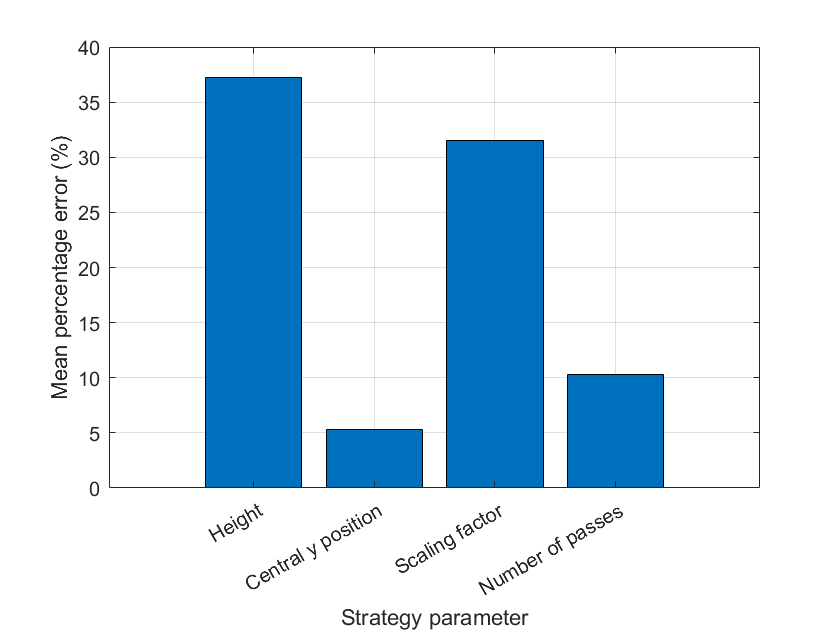

bar(avg{4})
xlabel('Strategy parameter')
ylabel('Mean percentage error (%)')
xticklabels({'Height','Central y position','Scaling factor','Number of passes'})
grid on

saveas(fig, '..\Python\data\plots\comb_l2_hor.jpg')

% Tri
fig = figure()

fig =   Figure (61) with properties:

      Number: 61
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


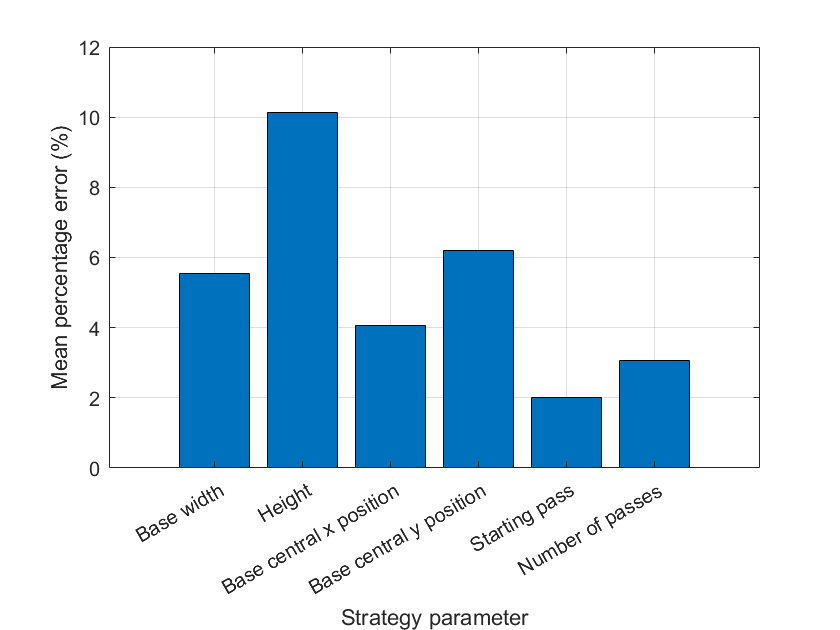

bar(avg{5})
xlabel('Strategy parameter')
ylabel('Mean percentage error (%)')
xticklabels({'Base width','Height','Base central x position','Base central y position','Starting pass','Number of passes'})
grid on

saveas(fig, '..\Python\data\plots\comb_l2_tri.jpg')

h = heatmap(conf)

h =   HeatmapChart with properties:

        XData: {5×1 cell}
        YData: {5×1 cell}
    ColorData: [5×5 double]

  Show all properties


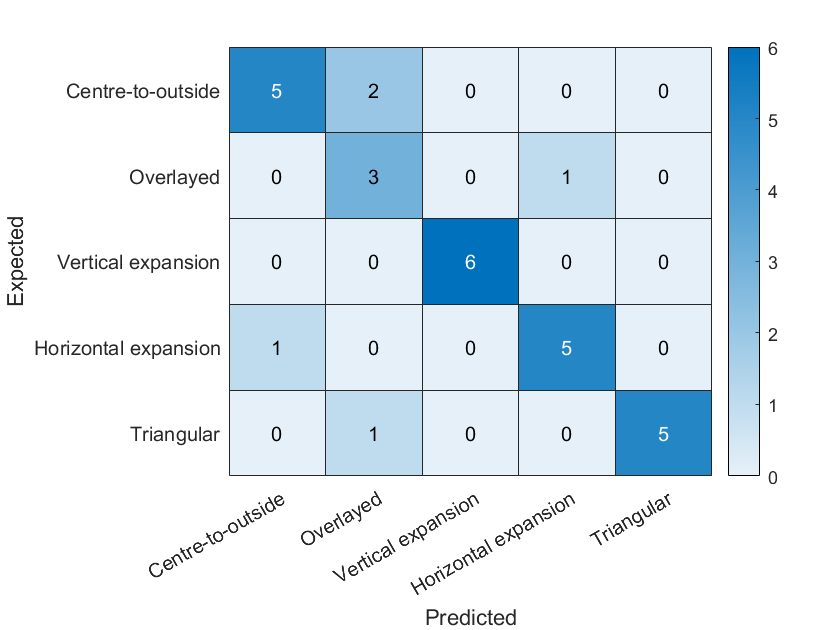

ax = gca;
ax.XData = ["Centre-to-outside" "Overlayed" "Vertical expansion" "Horizontal expansion" "Triangular"];
ax.YData = ["Centre-to-outside" "Overlayed" "Vertical expansion" "Horizontal expansion" "Triangular"];
ax.xlabel('Predicted')
ax.ylabel('Expected')
saveas(h, '..\Python\data\plots\comb_l1_conf.jpg')